TUTORIAL 10.1

a = [0 0 0 1 0 0 0];
f = [1 2 3 4 5];
g=imfilter(f,a,"full","conv")

g =      0     0     0     1     2     3     4     5     0     0     0


g = imfilter(f, a , "same", "conv")

g =      1     2     3     4     5


x = [140 108 94;89 99 125;121 134 221];
y = [-1 0 1;-2 0 2;-1 0 1];
z = imfilter(x,y, 'corr')

z =    315   -56  -315
   440   126  -440
   367   236  -367


z2 = imfilter(x, y, "conv")

z2 =   -315    56   315
  -440  -126   440
  -367  -236   367


TUTORIAL 10.2

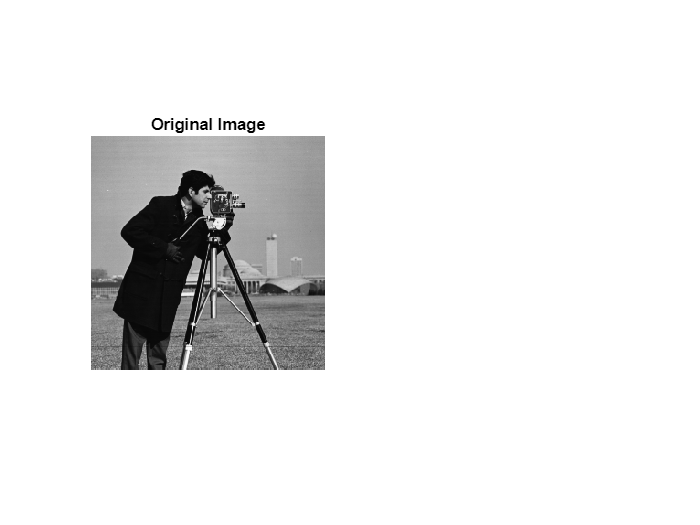

I = imread('cameraman.tif');
figure, subplot(1,2,1), imshow(I), title('Original Image');

fn = fspecial('average')

fn =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


laplace = fspecial("laplacian")

laplace =     0.1667    0.6667    0.1667
    0.6667   -3.3333    0.6667
    0.1667    0.6667    0.1667


sobelY = fspecial("sobel")

sobelY =      1     2     1
     0     0     0
    -1    -2    -1


sobelX = fspecial("sobel")'

sobelX =      1     0    -1
     2     0    -2
     1     0    -1


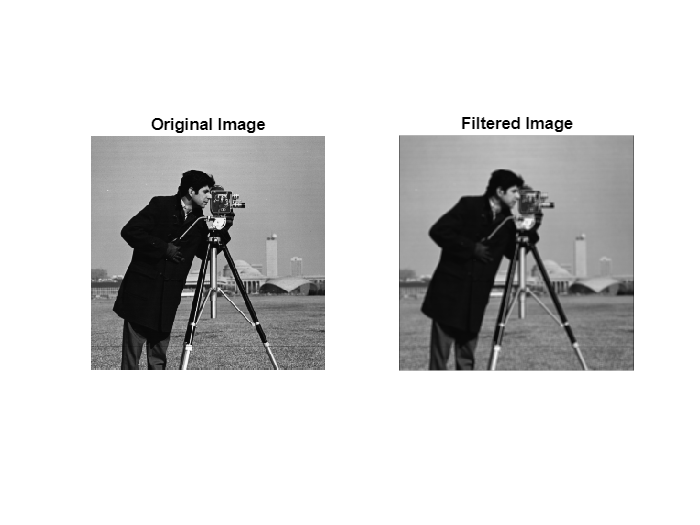

I_new = imfilter(I, fn);
subplot(1,2, 2); imshow(I_new); title("Filtered Image");

fn2 = [1 2 1; 2 4 2; 1 2 1]

fn2 =      1     2     1
     2     4     2
     1     2     1


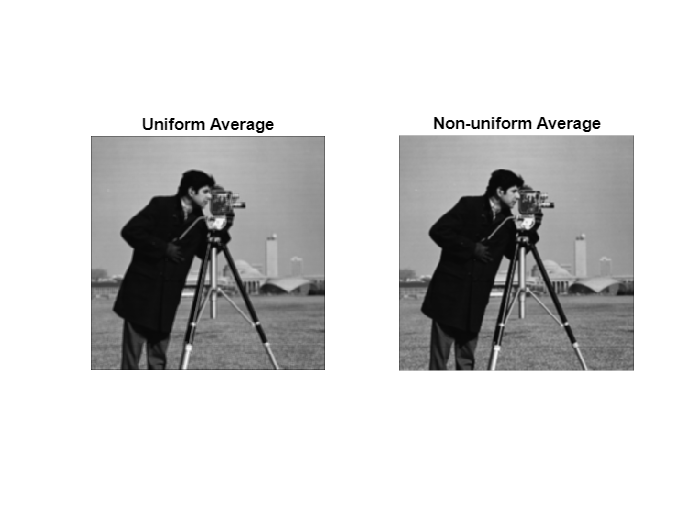

fn2 = fn2 * (1/16);
I_new2 = imfilter(I,fn2);
figure, subplot(1,2,1), imshow(I_new), title('Uniform Average');
subplot(1,2,2), imshow(I_new2), title('Non-uniform Average');

fn_gau = fspecial('gaussian',9,1)

fn_gau =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0002    0.0011    0.0018    0.0011    0.0002    0.0000    0.0000
    0.0000    0.0002    0.0029    0.0131    0.0215    0.0131    0.0029    0.0002    0.0000
    0.0000    0.0011    0.0131    0.0586    0.0965    0.0586    0.0131    0.0011    0.0000
    0.0001    0.0018    0.0215    0.0965    0.1592    0.0965    0.0215    0.0018    0.0001
    0.0000    0.0011    0.0131    0.0586    0.0965    0.0586    0.0131    0.0011    0.0000
    0.0000    0.0002    0.0029    0.0131    0.0215    0.0131    0.0029    0.0002    0.0000
    0.0000    0.0000    0.0002    0.0011    0.0018    0.0011    0.0002    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


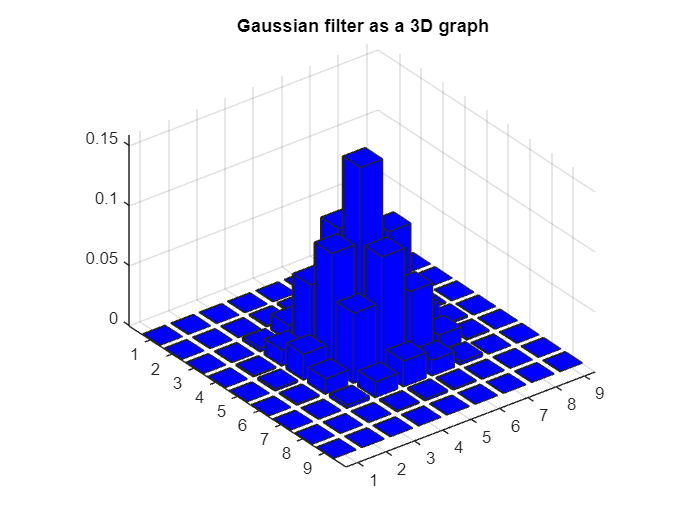

figure, bar3(fn_gau,'b');
title('Gaussian filter as a 3D graph');

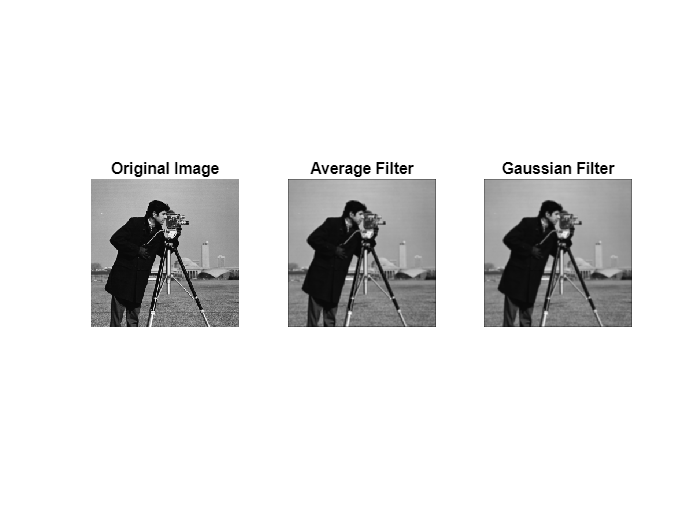

I_new3 = imfilter(I,fn_gau);
figure
subplot(1,3,1), imshow(I), title('Original Image');
subplot(1,3,2), imshow(I_new), title('Average Filter');
subplot(1,3,3), imshow(I_new3), title('Gaussian Filter');

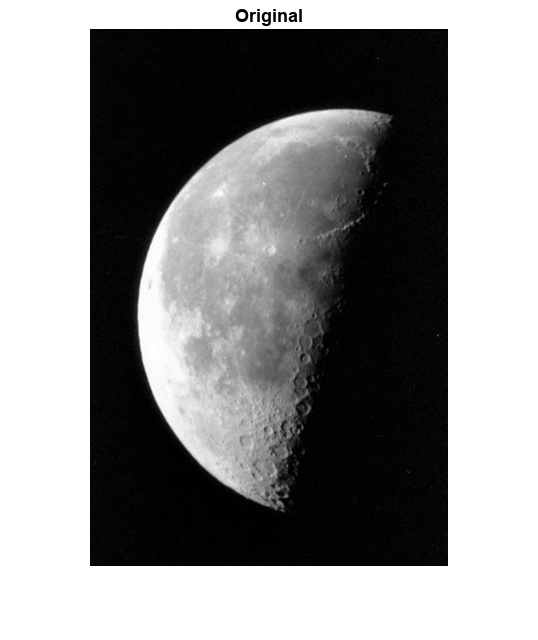

I = imread("moon.tif");
I_d = im2double(I);
figure; 
imshow(I_d, []); title("Original")

f = fspecial('laplacian',0)

f =      0     1     0
     1    -4     1
     0     1     0


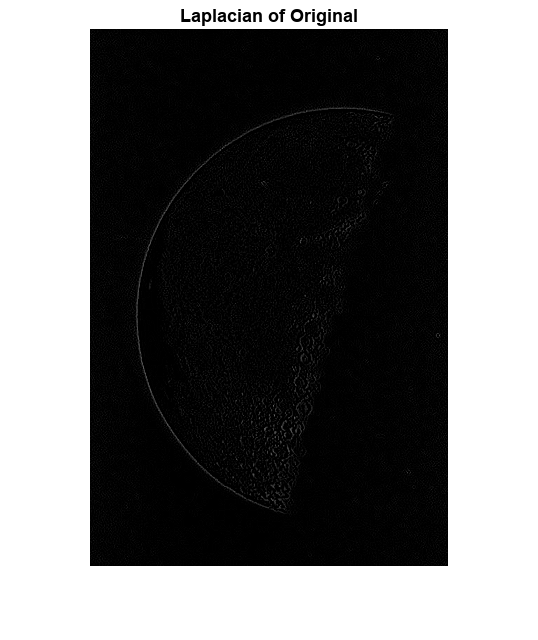

I_filt = imfilter(I_d,f);
imshow(I_filt), title('Laplacian of Original');

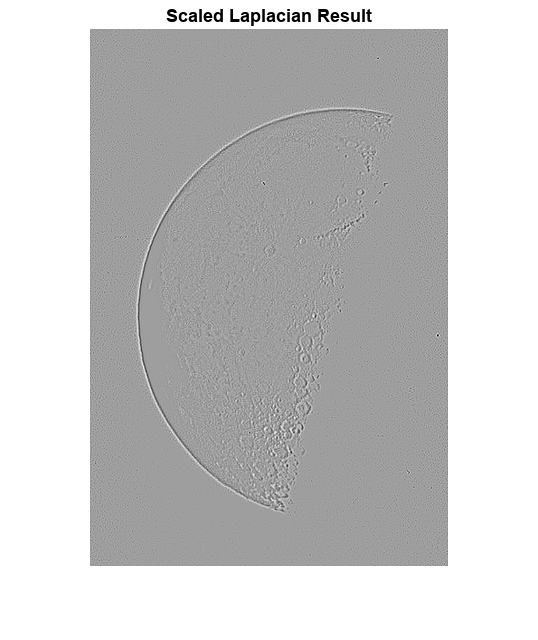

min(reshape(I_filt,[],1))
imshow(I_filt,[]); title("Scaled Laplacian Result")

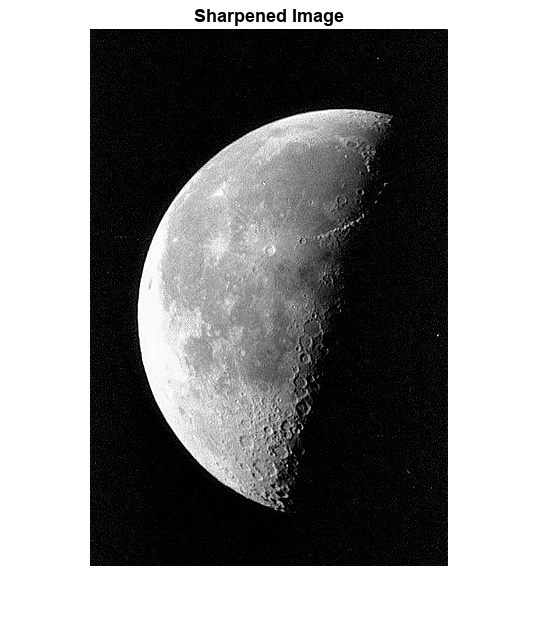

I_sharp = imsubtract(I_d,I_filt);
imshow(I_sharp), title('Sharpened Image');

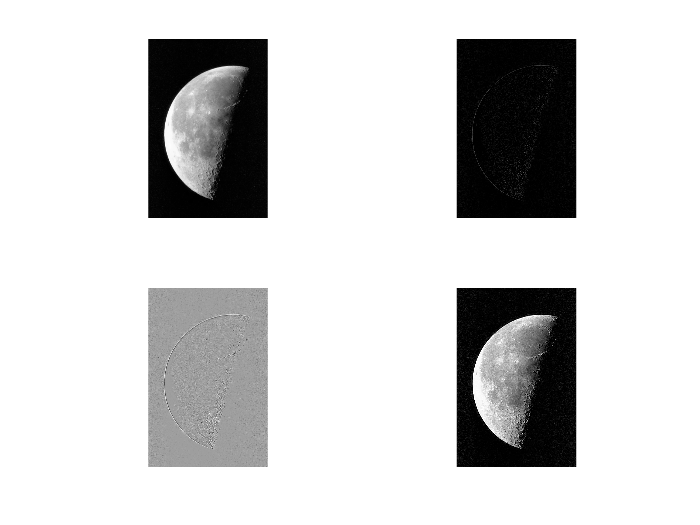

figure; 
subplot(2,2,1); imshow(I_d); 
subplot(2,2,2); imshow(I_filt); 
subplot(2,2,3); imshow(I_filt,[]);
subplot(2,2,4); imshow(I_sharp)

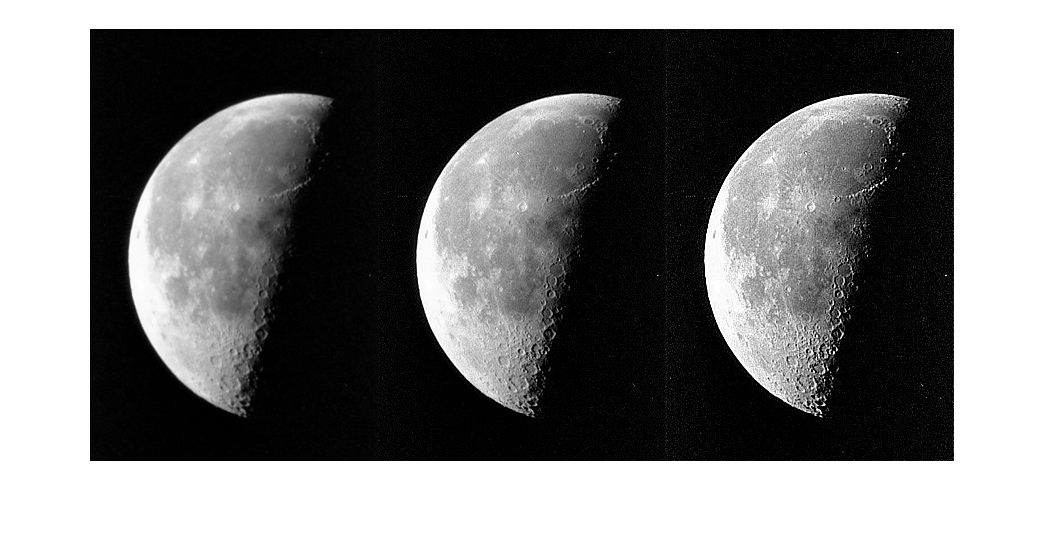

laplace = [-1 -1 -1; -1 9 -1; -1 -1 -1];
I_sharp2 = imfilter(I_d, laplace);
figure;
montage({I_d,I_sharp, I_sharp2})

f_blur = fspecial('average',5)

f_blur =     0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400


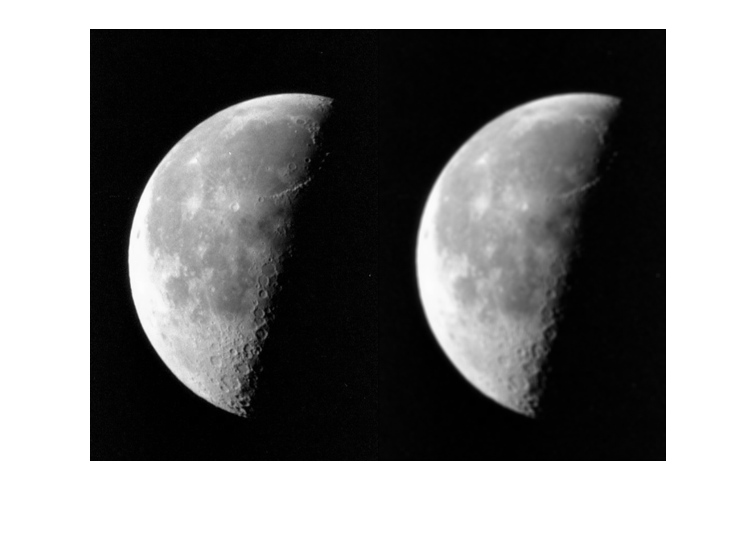

I_blur = imfilter(I,f_blur);
montage({I, I_blur});

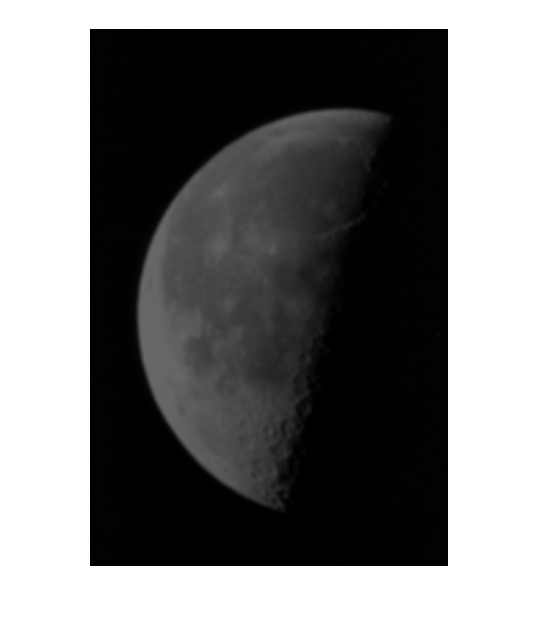

I_blur_adj = imadjust(I_blur,stretchlim(I_blur),[0 0.4]);
imshow(I_blur_adj)

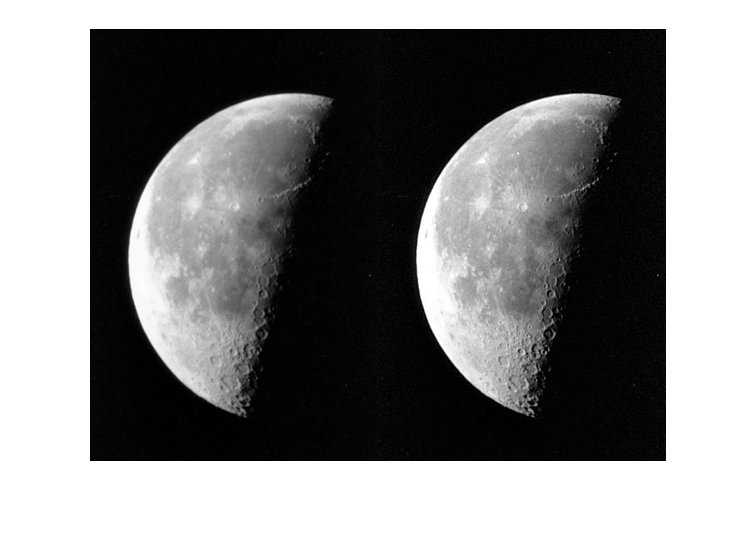

I_sharp = imsubtract(I,I_blur_adj);
I_sharp_adj = imadjust(I_sharp);
montage({I,I_sharp_adj})

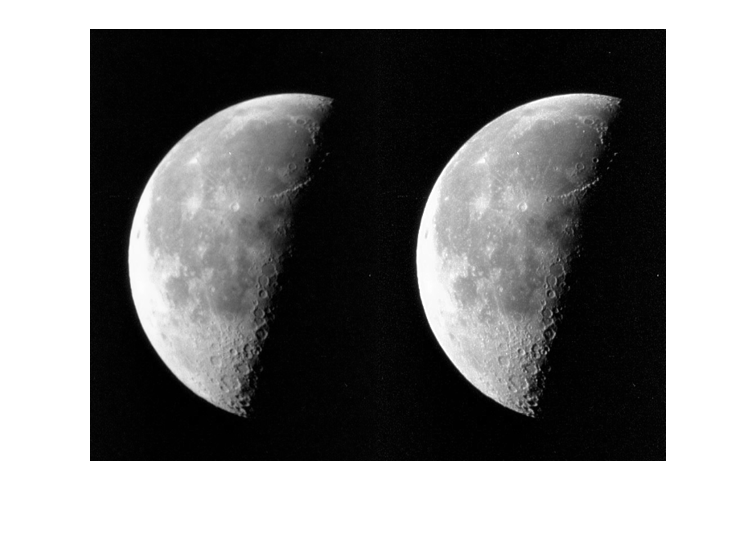

I_sharpening = imsubtract(I,I_blur);
I_sharp2 = imadd(I,I_sharpening);
montage({I, I_sharp2})

f_unsharp = fspecial('unsharp')

f_unsharp =    -0.1667   -0.6667   -0.1667
   -0.6667    4.3333   -0.6667
   -0.1667   -0.6667   -0.1667


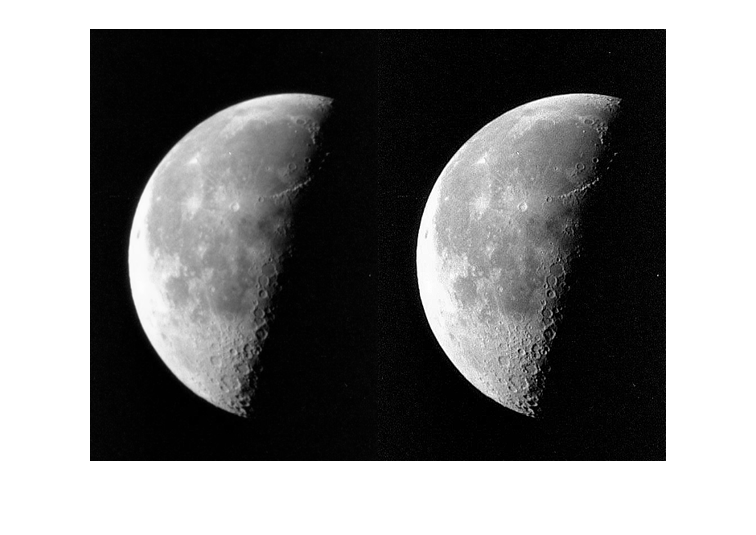

I_sharp3 = imfilter(I,f_unsharp);
montage({I, I_sharp3})